# CAPÍTULO 03 - CARACTERÍSTICAS GEOMÉTRICAS DE ÁREAS PLANAS

Calcula área, centroide, momentos de inercia y ejes principales de una sección definida mediante contornos o líneas medias.

Dimensión: la sección es un área 2D, incluso cuando pertenece a una estructura 3D. Su orientación espacial y las inercias se utilizan en los capítulos 7 y 9.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="poligonos" usa una celda por contorno [y z] y signos +1 para material, -1 para huecos. modo="pared_delgada" usa filas [yi zi yf zf espesor]. Todos los valores están en m.

modo = "poligonos";
contornos = {[-.06 -.10; .06 -.10; .06 .10; -.06 .10], ...
    [-.04 -.07; .04 -.07; .04 .07; -.04 .07]};
signos = [1 -1];
segmentos = [0 0 .12 0 .004; .12 0 .12 .20 .004; .12 .20 0 .20 .004];

## 2. Área, centroide y traslado de ejes


$$F=\int_DdA,\quad y_c=\frac{\int_Dy\,dA}{F},\quad z_c=\frac{\int_Dz\,dA}{F}$$



$$I_y=\int_D(z-z_c)^2dA,\quad I_z=\int_D(y-y_c)^2dA,\quad I_{yz}=\int_D(y-y_c)(z-z_c)dA$$


Las integrales poligonales se evalúan con los vértices y se trasladan al centroide. El orden horario o antihorario no cambia el resultado; el signo de material o hueco lo decides en signos.

if modo=="poligonos"
    resultado=rm_seccion(contornos,signos);
else
    assert(modo=="pared_delgada",'Modo no reconocido.');
    resultado=rm_pared(segmentos);
end
F=resultado.F;
centro=resultado.centro;
Iy=resultado.Iy; Iz=resultado.Iz; Iyz=resultado.Iyz;
disp(table(F,centro(1),centro(2),Iy,Iz,Iyz, ...
    'VariableNames',{'F_m2','yc_m','zc_m','Iy_m4','Iz_m4','Iyz_m4'}));

     F_m2     yc_m    zc_m      Iy_m4         Iz_m4         Iyz_m4  
    ______    ____    ____    __________    __________    __________

    0.0128     0       0      6.1707e-05    2.2827e-05    1.7347e-21



## 3. Ejes principales


$$\mathbf{J}=\begin{bmatrix}I_y&-I_{yz}\\-I_{yz}&I_z\end{bmatrix},\qquad \mathbf{J}\mathbf{v}=I\mathbf{v},\qquad i_k=\sqrt{I_k/F}$$


Los valores propios son las inercias principales y los vectores propios indican sus ejes. Si ambas inercias son iguales, la orientación principal no es única.

disp(table(resultado.principales,resultado.radios, ...
    'VariableNames',{'Inercia_principal_m4','Radio_giro_m'}));

    Inercia_principal_m4    Radio_giro_m
    ____________________    ____________

         6.1707e-05           0.069432  
         2.2827e-05            0.04223  



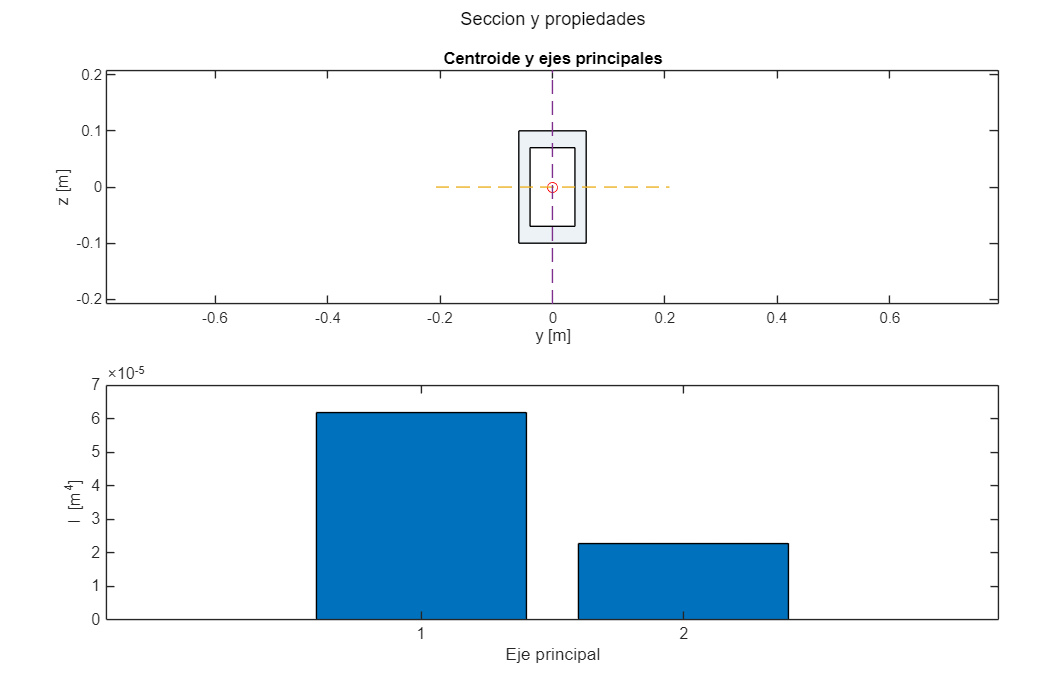

[figura,ejes]=rm_figura(2,'Seccion y propiedades'); hold(ejes(1),'on');
if modo=="poligonos"
    plot(ejes(1),resultado.region,'FaceColor',[.8 .85 .9]);
else
    for i=1:size(segmentos,1)
        plot(ejes(1),segmentos(i,[1 3]),segmentos(i,[2 4]),'k-','LineWidth',2);
    end
end
plot(ejes(1),centro(1),centro(2),'ro');
for k=1:2
    v=resultado.direcciones(:,k)*3*max(resultado.radios);
    plot(ejes(1),centro(1)+[-v(1) v(1)],centro(2)+[-v(2) v(2)],'--');
end
axis(ejes(1),'equal'); xlabel(ejes(1),'y [m]'); ylabel(ejes(1),'z [m]');
title(ejes(1),'Centroide y ejes principales');
bar(ejes(2),resultado.principales); ylabel(ejes(2),'I [m^4]'); xlabel(ejes(2),'Eje principal');

## Funciones utilizadas

rm_seccion: integra propiedades de polígonos. Aquí calcula el material restante después de descontar huecos.

rm_pared: integra propiedades de líneas con espesor. Aquí aproxima la sección de pared delgada.

eig: calcula valores y vectores propios. Aquí determina las inercias y direcciones principales.

sqrt: calcula la raíz cuadrada. Aquí convierte I/F en radio de giro.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Contornos poligonales con huecos sin solapamientos, o segmentos rectos de pared delgada. Las curvas se aproximan mediante vértices; la modalidad de pared delgada omite términos de espesor al cubo.

Conexión con lo anterior: F es el área utilizada en los capítulos 1 y 2. Iy, Iz e Iyz se reutilizan en flexión y estabilidad.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 03: calculo completado.');

Capitulo 03: calculo completado.
